2.1 Design Two Lowpass Filters Design two lowpass FIR filters with M D 30 and !Oc D 0:4� D 2�.2000=10000/, one using a Hamming window, the other with a Rectangular window. For the measurement of passband and stopband edges, there are two approaches: use the filterdesign GUI and read numbers from the plot, zooming when necessary, or export the filter coefficients from the GUI and use MATLAB to make plots of the magnitude of the frequency response using freekz (or freqz) and plot.

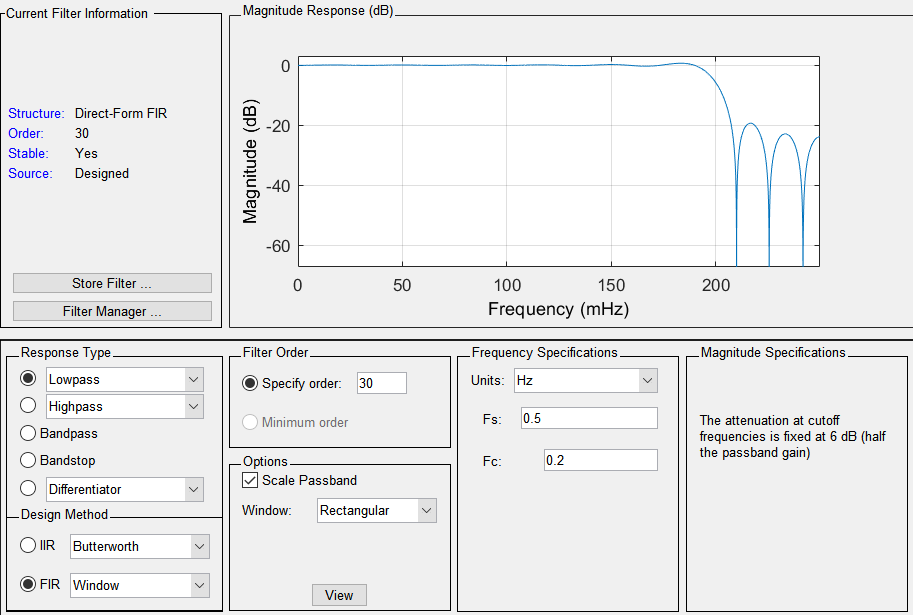

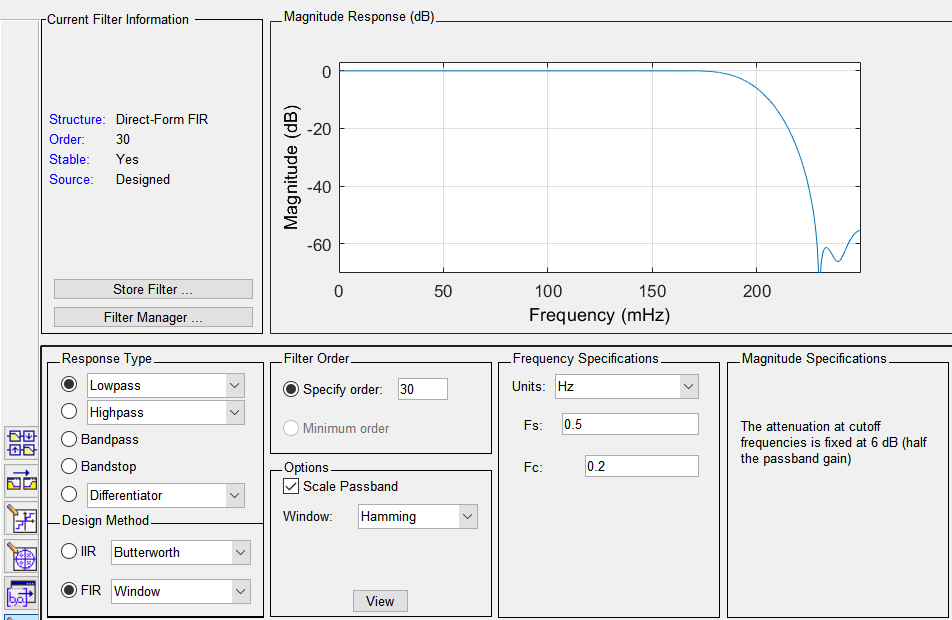

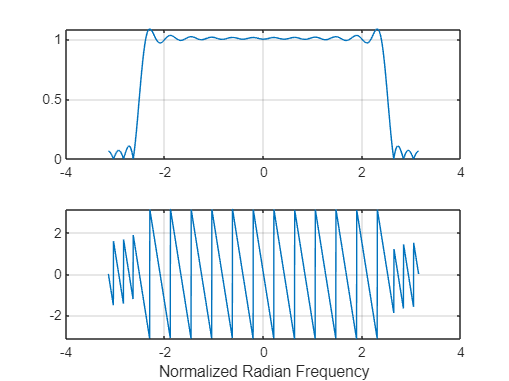

hammingFilter = [-2.49610766046471e-18	-0.00120408459375951	0.00279048831707927	-0.00423666924050868	0.00395148698036070	-9.67241718430074e-18	-0.00827504583864825	0.0186243264419525	-0.0254459967233954	0.0212822929150839	-2.40250362319728e-17	-0.0396757033135925	0.0920921859044279	-0.145420120238679	0.185311985725705	0.800409707327948	0.185311985725705	-0.145420120238679	0.0920921859044279	-0.0396757033135925	-2.40250362319728e-17	0.0212822929150839	-0.0254459967233954	0.0186243264419525	-0.00827504583864825	-9.67241718430074e-18	0.00395148698036070	-0.00423666924050868	0.00279048831707927	-0.00120408459375951	-2.49610766046471e-18];
rectangularFilter = [-3.14013607820487e-17	-0.0134566909869544	0.0234482590386118	-0.0254022806251628	0.0171266976197602	-3.14013607820487e-17	-0.0209326304241514	0.0381034209377442	-0.0435467667859934	0.0313989456362271	-3.14013607820487e-17	-0.0470984184543406	0.101609122500651	-0.152413683750977	0.188393673817363	0.805540702954445	0.188393673817363	-0.152413683750977	0.101609122500651	-0.0470984184543406	-3.14013607820487e-17	0.0313989456362271	-0.0435467667859934	0.0381034209377442	-0.0209326304241514	-3.14013607820487e-17	0.0171266976197602	-0.0254022806251628	0.0234482590386118	-0.0134566909869544	-3.14013607820487e-17];

ww = -pi:(pi/1000):pi; %-- omega hat frequency vector
rectWindow_filterDesign= freqz(rectangularFilter, 1, ww);
figure(1)
subplot(2,1,1);
plot(ww, abs(rectWindow_filterDesign)), grid on

subplot(2,1,2);
plot(ww, angle(rectWindow_filterDesign)), grid on
xlabel('Normalized Radian Frequency')

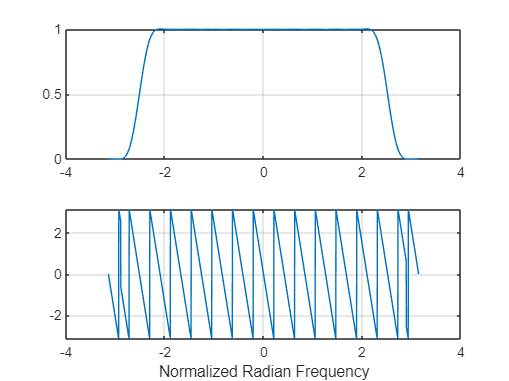



ww = -pi:(pi/1000):pi; %-- omega hat frequency vector
HammWindow_filterDesign= freqz(hammingFilter, 1, ww);
figure(1)
subplot(2,1,1);
plot(ww, abs(HammWindow_filterDesign)), grid on

subplot(2,1,2);
plot(ww, angle(HammWindow_filterDesign)), grid on
xlabel('Normalized Radian Frequency')

(a) For the filter obtained with the rectangular window, 

determine an accurate measurement of the passband edge .

Passband edge is defined as the maximum frequency that can pass through

the filter with  magnitude delta = 1-0.1 = 0.9. Because we have 1600 data

points, we can just the interactive figure viewer and place a marker,

f = 2.422

H(f) = 0.901

(b) For the filter obtained with the rectangular window, 

determine an accurate measurement of the stopband edge .

Assuming the stopband ripple specification is delta = 0.1.

We are looking for H(f) = 0.1, 

Finding if f = 2.607 , H(f) = 0.099

(c) For the filter obtained with the Hamming window, determine an accurate measurement of the passband edge assuming the passband ripple specification is delta = 0.1

using 2000 pts, 

If f = 1.382 , H(f) = 0.898 

(d) For the filter obtained with the Hamming window, determine an accurate measurement of the stopband edge  assuming the stopband ripple specification is ıs delta = 0.1

if f = 1.759   , H(f) = 0.102

(e) Question: is the cutoff frequency half way between omega_p and omega_s for both filters

%Rectangular filter: NO. The cutoff frequency, 0.4*pi = 1.256, 
% is not halfway between the pass and stop band. The pass band is 
% before the fp frequency. This is likely due to the settings I used when
% designing the filter, 
wp = 2.422;
ws = 2.607;
dist = (wp-ws)/(2*pi*2) %It is necessary to convert to frequency 

dist = -0.0147

wp + dist

ans = 2.4073

%Hamming Filter: This on is very nearly has a halfway point betwixt the stop and
%passband equivalent to the cutoff frequency.
wp = 1.382;
ws = 1.759;
dist = (wp-ws)/(2*pi*2) %It is necessary to convert to frequency 

dist = -0.0300

wp + dist

ans = 1.3520

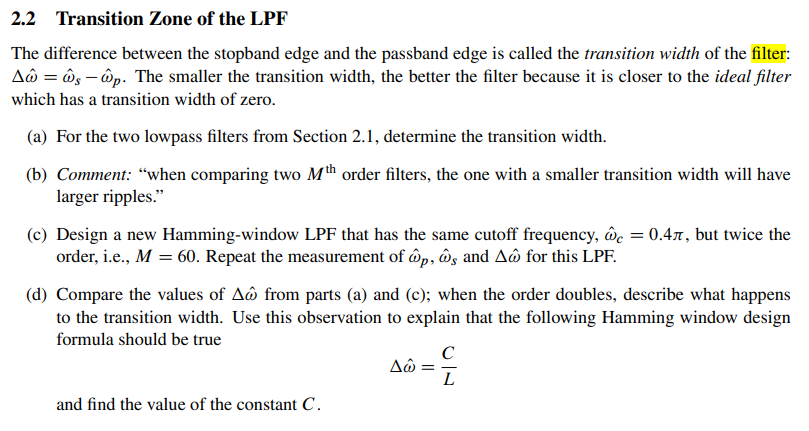

%part a: The transition width is defined below 
wp = 2.422;
ws = 2.607;
omega_delta_rect = (ws - wp)

omega_delta_rect = 0.1850


wp = 1.382;
ws = 1.759;
omega_delta_hamm = (ws - wp)

omega_delta_hamm = 0.3770

part b:

I think this is generally true, and you can see this is the case for the above. 

The rectangulare windowing has a much larger ripple, which has the effect of producing a smaller transition width. 

In order to obtain a sharper cutoff, we will need to superimpose more sinusoidal terms on the filter, which in term produces a larger amplitude in our ripple. 

There is a tradeoff between sharpness of the transition, and the size of our ripple. 

Part c: 

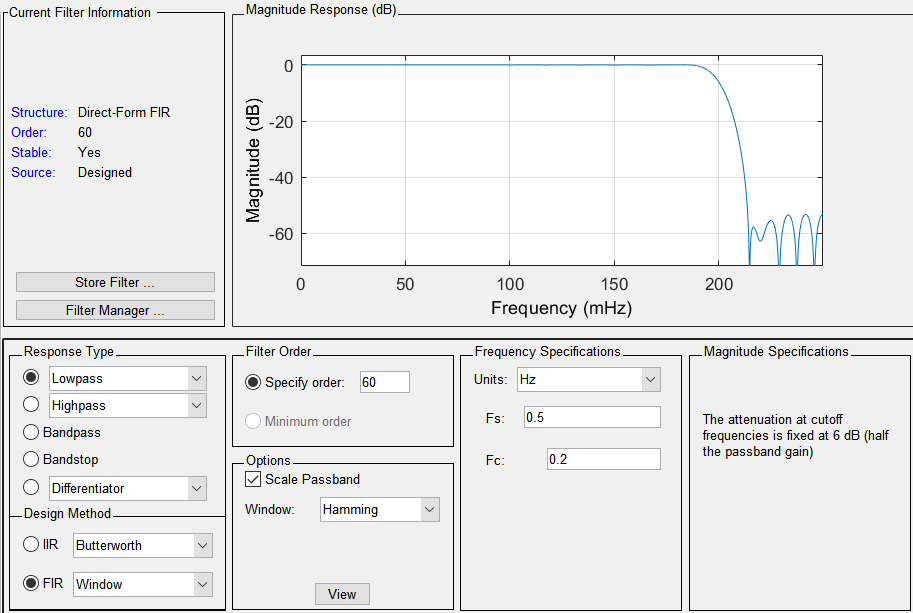

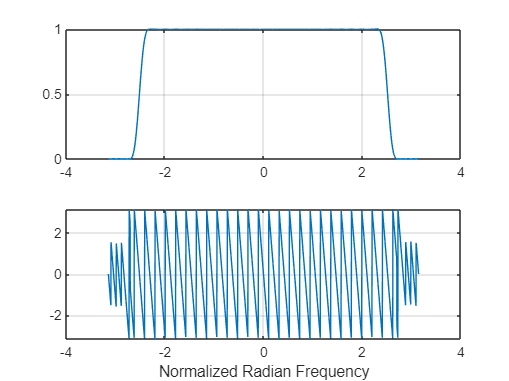

hammingFilter_60 = [-2.49550582292030e-18	-0.000532533938068979	0.000973890027361538	-0.00114972377842598	0.000862100401070419	-4.41792853655145e-18	-0.00130888713243858	0.00260884175438266	-0.00319604933354946	0.00240279820038129	-9.67008506381617e-18	-0.00347604918259487	0.00669303856222975	-0.00791517884463533	0.00575384573266341	-1.68446643047120e-17	-0.00786134951600030	0.0148061290019539	-0.0172135852720055	0.0123704991343014	-2.40192435456079e-17	-0.0168512958598457	0.0320905790057641	-0.0381477652904858	0.0284511889613488	-2.92714000728726e-17	-0.0449264536296970	0.0986650584555667	-0.149884398309039	0.186676940742619	0.800216720214288	0.186676940742619	-0.149884398309039	0.0986650584555667	-0.0449264536296970	-2.92714000728726e-17	0.0284511889613488	-0.0381477652904858	0.0320905790057641	-0.0168512958598457	-2.40192435456079e-17	0.0123704991343014	-0.0172135852720055	0.0148061290019539	-0.00786134951600030	-1.68446643047120e-17	0.00575384573266341	-0.00791517884463533	0.00669303856222975	-0.00347604918259487	-9.67008506381617e-18	0.00240279820038129	-0.00319604933354946	0.00260884175438266	-0.00130888713243858	-4.41792853655145e-18	0.000862100401070419	-0.00114972377842598	0.000973890027361538	-0.000532533938068979	-2.49550582292030e-18];

ww = -pi:(pi/1000):pi; %-- omega hat frequency vector
HammWindow_filterDesign= freqz(hammingFilter_60, 1, ww);
figure(1)
subplot(2,1,1);
plot(ww, abs(HammWindow_filterDesign)), grid on

subplot(2,1,2);
plot(ww, angle(HammWindow_filterDesign)), grid on
xlabel('Normalized Radian Frequency')


wp = 2.415;
ws = 2.607;
omega_delta_hamm_M60 = (ws - wp)

omega_delta_hamm_M60 = 0.1920

Part d: 

Notice, here the transition frequency is small than it was previously, 

and we have a much smaller ripple. This was expected, baseed on our rule from the previous section. 

Comparing the ratio of the transition widths, we can see that by changing M to be twice as large, M = 30 --> M =60, we find that this nearly halves the transition frequency size. 

Furthermomre, we see C = $\Delta \omega *\left(M+1\right)$, Where M=60 : C = 11.712 and M=30: 11.687

Thus, the role of C is to serve as a rough constant what allows us to estimate the order of our filter give a transition frequency, $\Delta \omega$.

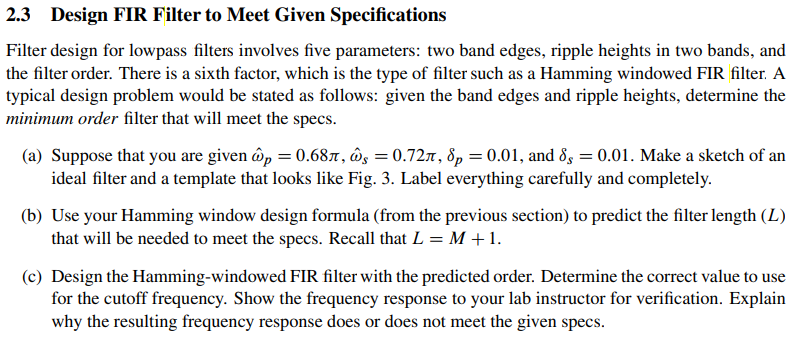

part a:

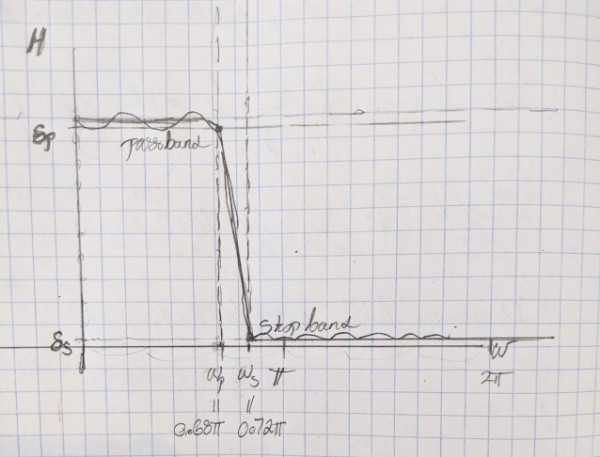

%part b:
%We will use the equation above, and compute L and M. 
%It is important to note we choose an arbitrary value of C, the higher the
%value the sharper the cutoff frequency.
wp = 0.68*pi;
ws = 0.72*pi;
omega_delta = (ws- wp)

omega_delta = 0.1257

C = 11.7

C = 11.7000

L = C/omega_delta 

L = 93.1056

M = L-1 

M = 92.1056

$\omega_s =\frac{0\ldotp 72}{2}=0\ldotp 36$, $\omega_c =\frac{0\ldotp 68\;}{2}+\frac{0\ldotp 72-0\ldotp 68\;}{2}*\frac{1\;}{2}=0\ldotp 35$

part C: 

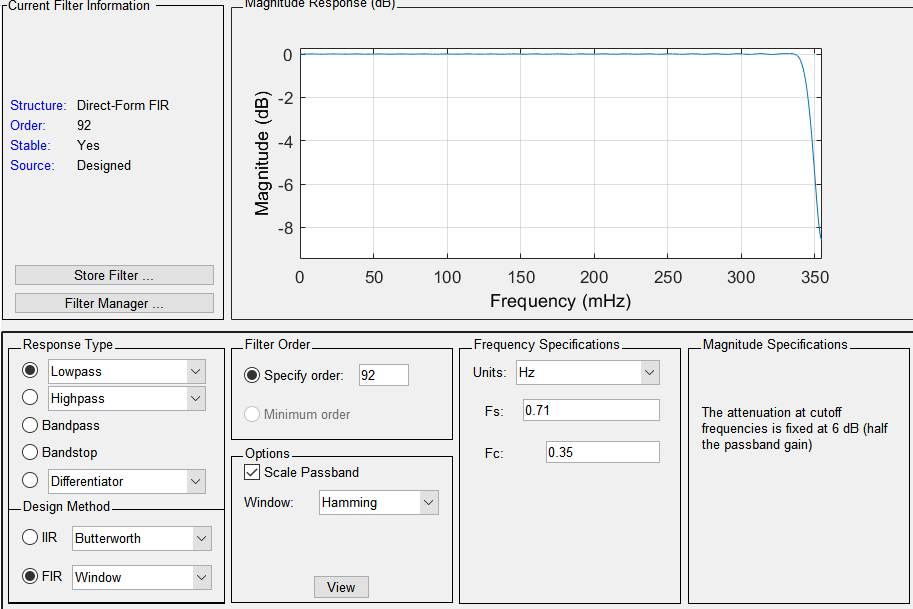

I had to enter a Fs = 0.71 

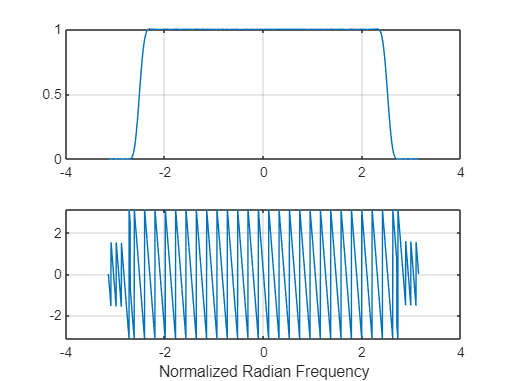

hammingFilter_92 = [-0.000495142426100586	0.000523799599758809	-0.000567395399399909	0.000627533035100498	-0.000705711268673852	0.000803306067700542	-0.000921553156733333	0.00106153165648544	-0.00122414899265008	0.00141012724484955	-0.00161999109317726	0.00185405750500147	-0.00211242728828991	0.00239497861985194	-0.00270136263775994	0.00303100116699775	-0.00338308662629734	0.00375658414238467	-0.00415023587568415	0.00456256753916298	-0.00499189706966242	0.00543634538900150	-0.00589384917058089	0.00636217550638831	-0.00683893834943986	0.00732161658798867	-0.00780757359050185	0.00829407804463227	-0.00877832589936711	0.00925746320737162	-0.00972860965440393	0.0101888825546602	-0.0106354210851209	0.0110654105284659	-0.0114761062929585	0.0118648574788894	-0.0122291297647002	0.0125665273917634	-0.0128748140349099	0.0131519323560915	-0.0133960220509496	0.0136054362123964	-0.0137787558514654	0.0139148024334848	-0.0140126483068853	0.0140716249224896	0.986393013389590	0.0140716249224896	-0.0140126483068853	0.0139148024334848	-0.0137787558514654	0.0136054362123964	-0.0133960220509496	0.0131519323560915	-0.0128748140349099	0.0125665273917634	-0.0122291297647002	0.0118648574788894	-0.0114761062929585	0.0110654105284659	-0.0106354210851209	0.0101888825546602	-0.00972860965440393	0.00925746320737162	-0.00877832589936711	0.00829407804463227	-0.00780757359050185	0.00732161658798867	-0.00683893834943986	0.00636217550638831	-0.00589384917058089	0.00543634538900150	-0.00499189706966242	0.00456256753916298	-0.00415023587568415	0.00375658414238467	-0.00338308662629734	0.00303100116699775	-0.00270136263775994	0.00239497861985194	-0.00211242728828991	0.00185405750500147	-0.00161999109317726	0.00141012724484955	-0.00122414899265008	0.00106153165648544	-0.000921553156733333	0.000803306067700542	-0.000705711268673852	0.000627533035100498	-0.000567395399399909	0.000523799599758809	-0.000495142426100586];

ww = -pi:(pi/2000):pi; %-- omega hat frequency vector
HammWindow_filterDesign= freqz(hammingFilter_60, 1, ww);
figure(1)
subplot(2,1,1);
plot(ww, abs(HammWindow_filterDesign)), grid on

subplot(2,1,2);
plot(ww, angle(HammWindow_filterDesign)), grid on
xlabel('Normalized Radian Frequency')

Analyzing the transition frequency, given our 0.01dB ripple 

H(f) = 0.99 for f = 2.35

H(f) = 0.01 for f = 2.668

wp = 2.35;
ws = 2.668;
omega_delta_hamm_M60 = (ws - wp)

omega_delta_hamm_M60 = 0.3180

This does not QUITE reach our specifications, where we should have a transition frequency of ~ 0.04pi. 

%%%%UPDATE 